# **Homodyne detection Equations : **

We consider the following system : 

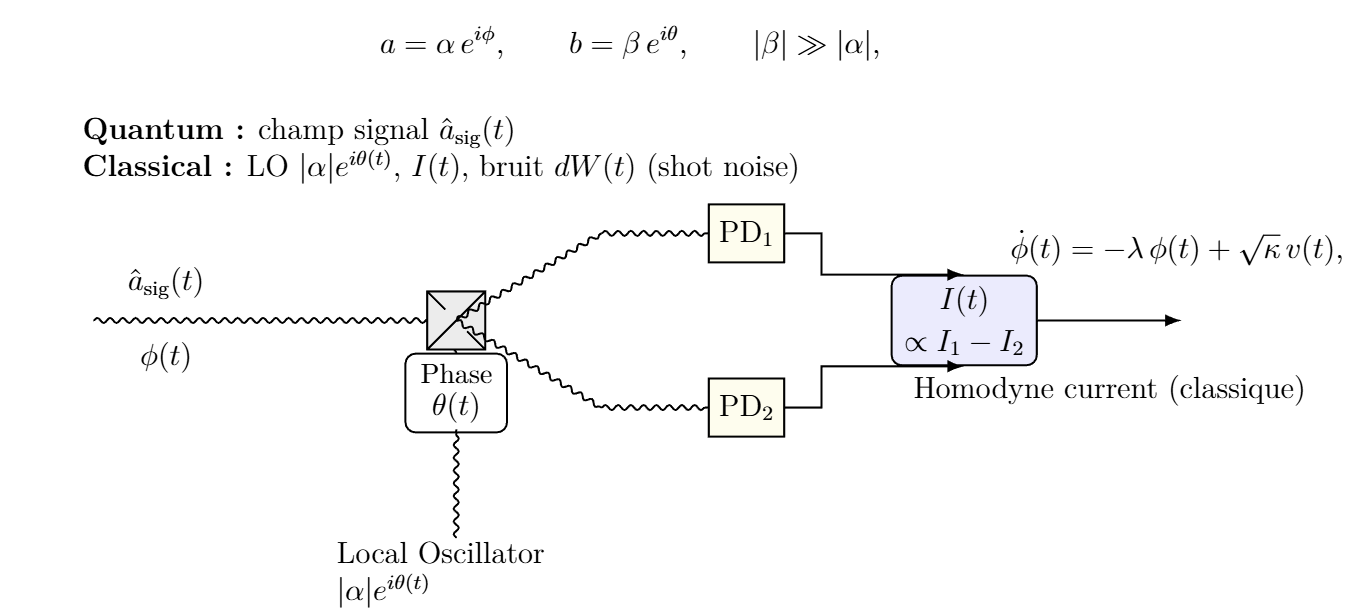

The equation of the OU noise signal is given by : 


$$    \dot{\phi}(t) = -\lambda\,\phi(t) + \sqrt{\kappa}\,v(t),$$


The homodyne measurement gives us the second equation : 


$$    y_c(t) = \phi(t) + \frac{1}{2|\alpha|}\, w(t),$$


clear; close all; clc;

%% --- Paramètres du modèle physique ---
lambda = 5;          % taux de relaxation λ (>0)
kappa  = 2;          % intensité de diffusion κ (>0)
alpha  = 5;          % amplitude du LO |α| (plus grand = mesure plus précise)
eta = 0.9;

%% --- Discrétisation temporelle ---
dt = 1e-3;           % pas de temps
T  = 1;              % horizon final (en secondes)
N  = round(T/dt);    % nombre de pas

t = (0:N)*dt;        % vecteur temps

# Generation of the signal OU noise : Generation of the Signal

The true phase is generated as an Ornstein--Uhlenbeck process obeying and is simulated using the Euler--Maruyama scheme


$$\[
d\phi(t)= -\lambda\,\phi(t)\,dt + \sqrt{\kappa}\,dW(t),
\]
\[
\phi_{k+1} = \phi_k - \lambda\,dt\,\phi_k + \sqrt{\kappa\,dt}\,\xi_k,\qquad \xi_k\sim\mathcal{N}(0,1).
\]
$$


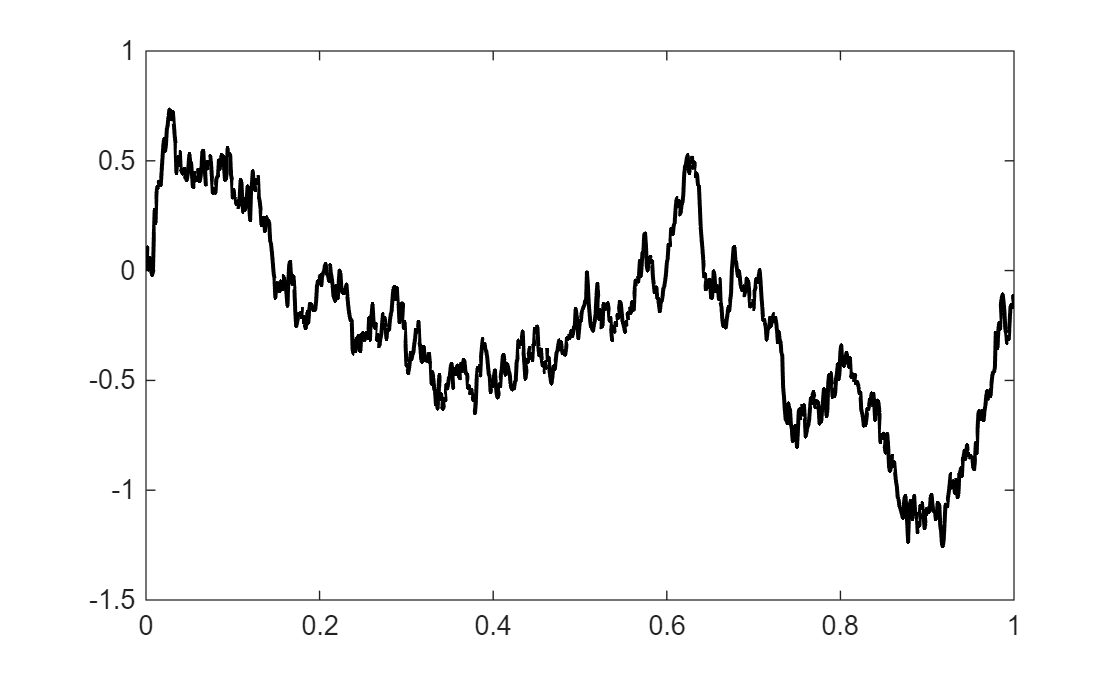

%% --- Simulation du vrai processus de phase (OU) ---
phi_true       = zeros(1, N+1);
phi_true(1)    = 0;              % condition initiale de la phase réelle

for k = 1:N
    % Euler-Maruyama pour : dφ = (-λ φ) dt + sqrt(κ) dW
    phi_true(k+1) = phi_true(k) ...
        + dt * (-lambda * phi_true(k)) ...
        + sqrt(kappa * dt) * randn;
end

plot(t, phi_true, 'k', 'LineWidth', 1.5);

# Estimation via Continious =) Discrete Kalman filtering : 

We have : 


$$
\[
A = -\lambda,\qquad B = 0,\qquad C = 1.
\]
\[R=\frac{1}{4|\alpha|^2}\]
\[
\dot{\hat{\phi}}(t) = A\hat{\phi}(t) + K(t)\bigl(y_c(t)-C\hat{\phi}(t)\bigr)
\]
uses a gain $K(t)$ obtained from the scalar Riccati equation
\[
\dot{P}(t) = 2AP(t) + Q - \frac{P(t)^2}{R}
          = -2\lambda P(t) + \kappa - 4|\alpha|^2\,P(t)^2.
\]
Thus the Kalman gain is
\[
K(t) = \frac{P(t)}{R} = 4|\alpha|^2\,P(t).
\]
$$


The continuous-time Riccati equation is : 


$$
\[\dot{P} = 2AP + W - P^2 V^{-1}\] yields
\[
P_{k+1}=P_k + \Delta t\bigl(-2\lambda P_k + Q - P_k^2/R\bigr),\qquad
K_{k+1}=\frac{P_{k+1}}{R},
\]
which leads to the Kalman update 
$\hat{\phi}_{k+1}=\hat{\phi}_k+\Delta t\bigl(-\lambda\hat{\phi}_k + K_{k+1}(y_c[k]-\hat{\phi}_k)\bigr)$.
$$


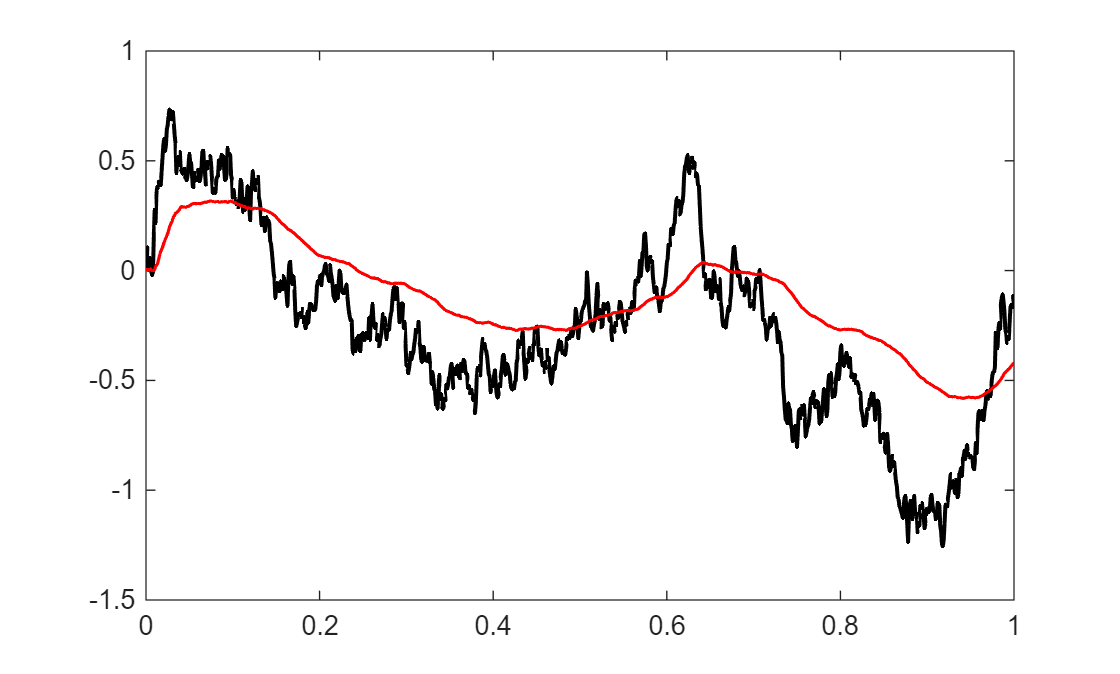

R_meas   = 1 / (4 * alpha^2*eta);     % variance de mesure
sigma_w  = sqrt(R_meas);

y_meas = phi_true(1:end-1) + sigma_w * randn(1, N);  % y[k] défini pour k=1..N
Q_proc = kappa;       % Q = κ pour notre modèle OU

% Initialisation
phi_hat_K = zeros(1, N+1);    % estimation Kalman
P         = zeros(1, N+1);    % variance d'erreur
phi_hat_K(1) = 0;             % estimateur initial
P(1)       = 1;               % variance initiale

for k = 1:N
    % --- 1) Riccati (Euler) : P_{k+1} = P_k + dt ( -2λ P_k + Q - P_k^2 / R ) ---
    P(k+1) = P(k) + dt * ( -2*lambda*P(k) + Q_proc - (P(k)^2)/R_meas );
    
    % --- 2) Gain de Kalman ---
    Kk = P(k+1) / R_meas;   % scalaire
    
    % --- 3) Mise à jour de l'estimateur ---
    innov = y_meas(k) - phi_hat_K(k);
    phi_hat_K(k+1) = phi_hat_K(k) ...
        + dt * ( -lambda*phi_hat_K(k) + Kk * innov );
end

plot(t, phi_true, 'k', 'LineWidth', 1.5); hold on;
plot(t, phi_hat_K, 'r', 'LineWidth', 1.2);

# Estimation via LUENBERGER : 


$$
\[
\dot{\hat{\phi}}(t)
= A\hat{\phi}(t) + L\bigl(y(t) - C\hat{\phi}(t)\bigr)
= -\lambda\,\hat{\phi}(t) + L\bigl(y(t)-\hat{\phi}(t)\bigr),
\]
where $L$ is a user-defined gain (pole placement).  The noisy homodyne
measurement $y(t)=y_c(t)$ is injected directly in the correction term.
$$


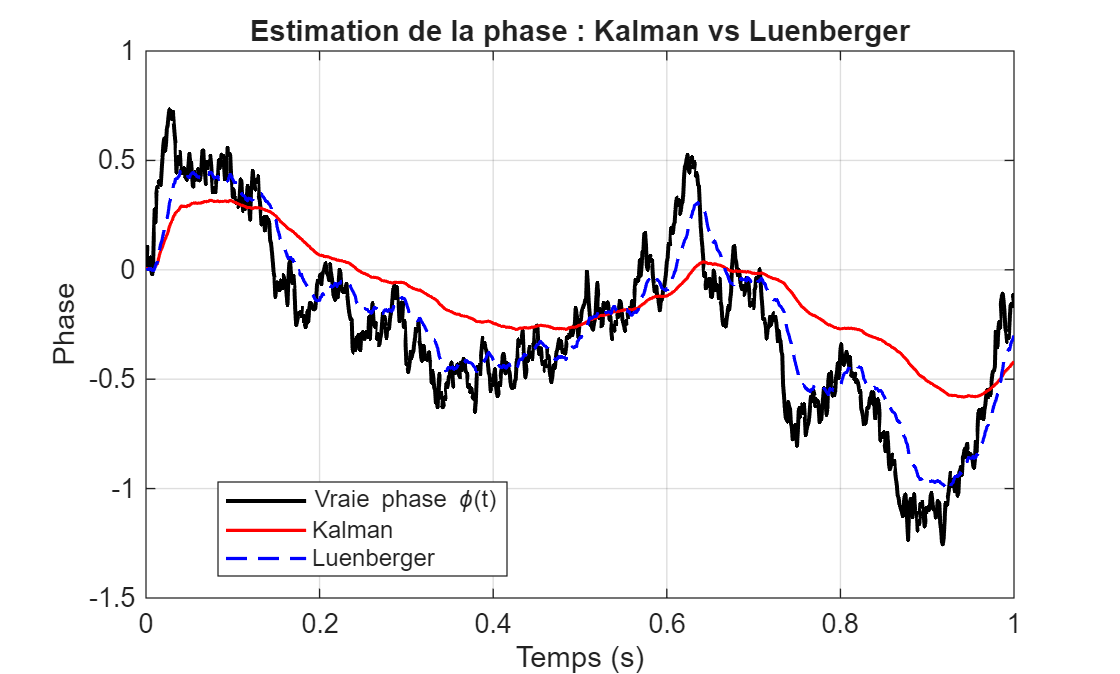

L = 10 * lambda;      % gain Luenberger
phi_hat_L = zeros(1, N+1);
phi_hat_L(1) = 0;     % condition initiale

for k = 1:N
    innov_L = y_meas(k) - phi_hat_L(k);
    % Euler pour : dφ_hat = (-λ φ_hat + L (y - φ_hat)) dt
    phi_hat_L(k+1) = phi_hat_L(k) ...
        + dt * ( -lambda * phi_hat_L(k) + L * innov_L );
end


figure;
plot(t, phi_true, 'k', 'LineWidth', 1.5); hold on;
plot(t, phi_hat_K, 'r', 'LineWidth', 1.2);
plot(t, phi_hat_L, 'b--', 'LineWidth', 1.2);
legend('Vraie phase \phi(t)', 'Kalman', 'Luenberger', 'Location', 'Best');
xlabel('Temps (s)');
ylabel('Phase');
title('Estimation de la phase : Kalman vs Luenberger');
grid on;

% Erreurs quadratiques moyennes
err_K = phi_true - phi_hat_K;
err_L = phi_true - phi_hat_L;

mse_K = mean(err_K.^2);
mse_L = mean(err_L.^2);

fprintf('MSE Kalman     : %.4e\n', mse_K);

MSE Kalman     : 8.6401e-02


fprintf('MSE Luenberger : %.4e\n', mse_L);

MSE Luenberger : 2.2811e-02


# Discrete-Discrete Kalman filtering Vs LUENBERGER :


$$Ornstein--Uhlenbeck process:
\[
\phi_{k+1} = (1-\lambda\,\Delta t)\,\phi_k 
            + \sqrt{\kappa\,\Delta t}\,\xi_k,
\qquad \xi_k\sim\mathcal{N}(0,1).
\]
Thus the discrete state model is
\[
a = 1-\lambda\,\Delta t,
\qquad 
Q_d = \kappa\,\Delta t.
\]

The optimal discrete Kalman filter then uses the standard update equations:
\[
P_{k+1}^{-} = a^{2}P_k + Q_d,
\qquad
K_k = \frac{P_{k+1}^{-}}{P_{k+1}^{-} + R},
\]
\[
\hat\phi_{k+1}
= \phi_{\mathrm{pred}}
+ K_k\bigl(y_k - \phi_{\mathrm{pred}}\bigr),
\qquad
\phi_{\mathrm{pred}}=a\,\hat\phi_k.
\]
This yields a clear separation between prediction, Kalman gain computation,
and measurement update.
$$


dt = 1e-3;           
T  = 1;              % total simulation time (seconds)
N  = round(T/dt);    % number of time steps

t = (0:N)*dt;        % time vector (N+1 points)

phi_true    = zeros(1, N+1);
phi_true(1) = 0;     % initial true phase

for k = 1:N
    phi_true(k+1) = phi_true(k) ...
        + dt * (-lambda * phi_true(k)) ...
        + sqrt(kappa * dt) * randn;
end

% Measurement noise variance: R = 1 / (4 |α|^2*eta)
R_meas  = 1 / (4 * alpha^2*eta);
sigma_w = sqrt(R_meas);

% Measurements defined for k = 1..N (we use φ_true(1..N))
y_meas = phi_true(1:end-1) + sigma_w * randn(1, N);




a  = 1 - lambda * dt;   % discrete state matrix A_d (scalar)
Qd = kappa * dt;        % discrete process noise variance

% Kalman variables
phi_hat_K = zeros(1, N+1);   % estimated phase
P         = zeros(1, N+1);   % estimation error variance

% Initial conditions (can be tuned)
phi_hat_K(1) = 0;            % initial estimate
P(1)        = 1;             % initial variance

for k = 1:N
    
    phi_pred = a * phi_hat_K(k);
    
    % Variance prediction
    P_pred = a^2 * P(k) + Qd;
    
    % --- (2) Kalman gain ---
    % For scalar case: K = P_pred / (P_pred + R)
    Kk = P_pred / (P_pred + R_meas);
    
    innov = y_meas(k) - phi_pred;          % innovation (measurement - prediction)
    phi_hat_K(k+1) = phi_pred + Kk * innov;
    
    % Updated variance
    P(k+1) = (1 - Kk) * P_pred;
end


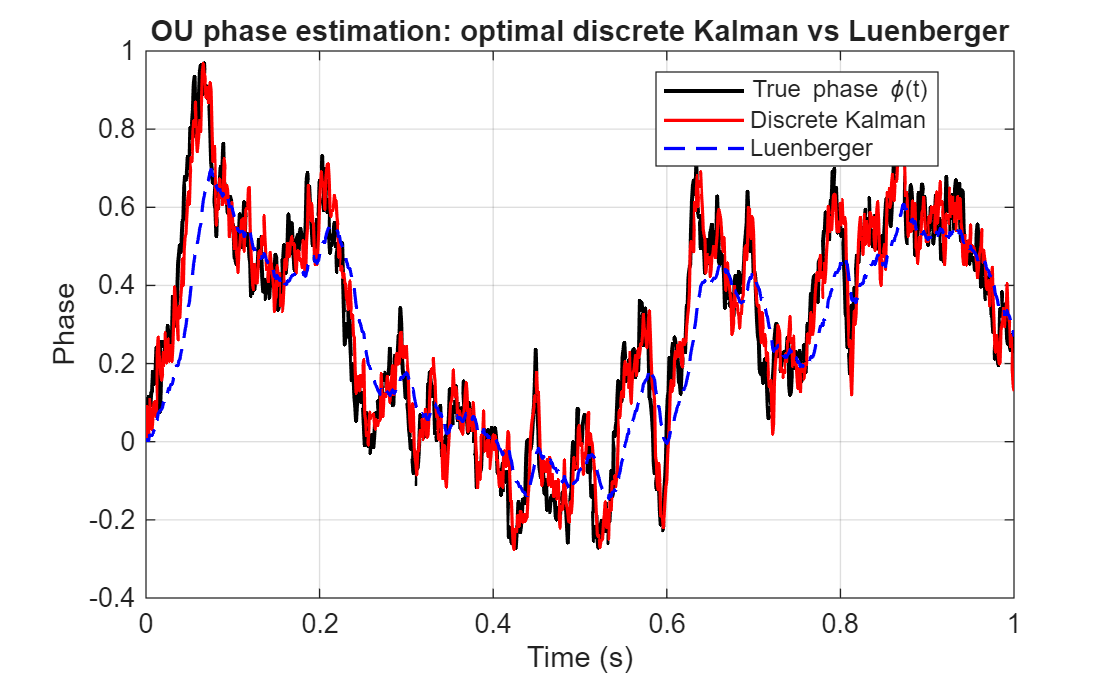

L = 10 * lambda;        

phi_hat_L    = zeros(1, N+1);
phi_hat_L(1) = 0;

for k = 1:N
    innov_L = y_meas(k) - phi_hat_L(k);
    % Continuous observer integrated with Euler:
    % dφ_hat = (-λ φ_hat + L (y - φ_hat)) dt
    phi_hat_L(k+1) = phi_hat_L(k) ...
        + dt * ( -lambda * phi_hat_L(k) + L * innov_L );
end

figure;
plot(t, phi_true, 'k', 'LineWidth', 1.5); hold on;
plot(t, phi_hat_K, 'r', 'LineWidth', 1.2);
plot(t, phi_hat_L, 'b--', 'LineWidth', 1.2);
legend('True phase \phi(t)', 'Discrete Kalman', 'Luenberger', 'Location', 'Best');
xlabel('Time (s)');
ylabel('Phase');
title('OU phase estimation: optimal discrete Kalman vs Luenberger');
grid on;


% Mean squared errors (over 0..T)
err_K = phi_true - phi_hat_K;
err_L = phi_true - phi_hat_L;

mse_K = mean(err_K.^2);
mse_L = mean(err_L.^2);

fprintf('MSE (Discrete Kalman) : %.4e\n', mse_K);

MSE (Discrete Kalman) : 5.6569e-03


fprintf('MSE (Luenberger)      : %.4e\n', mse_L);

MSE (Luenberger)      : 1.7903e-02
